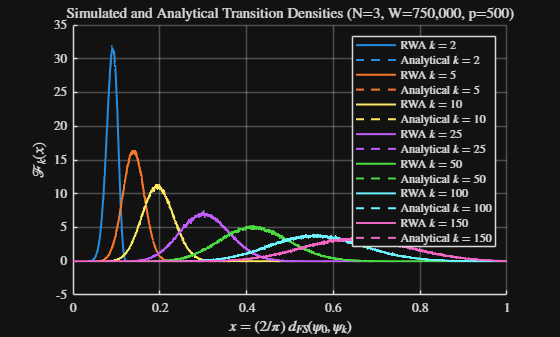

set(groot,'defaultTextInterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

filename = "analytic_CPn_density_n8_a0.100_p500_k2-150.csv";

Analytical_Results = readmatrix(filename);

step_size_grid = (2/pi) * Analytical_Results(1, 2:end);
Analytical_PDF = (pi/2) * Analytical_Results(2:end, 2:end);

Num_Bins    = 2000;
Bin_Edges   = linspace(0, 1, Num_Bins + 1);
Bin_Centers = 0.5 * (Bin_Edges(1:end-1) + Bin_Edges(2:end));

Selected_Steps = [2, 5, 10, 25, 50, 100, 150];

Residuals   = zeros(numel(Selected_Steps), numel(step_size_grid));
L2_errors   = zeros(numel(Selected_Steps), 1);
Linf_errors = zeros(numel(Selected_Steps), 1);

plot_colours = lines(numel(Selected_Steps));

figure('Name', 'Random Walk Algorithm Benchmarking');
hold on

legend_entries = cell(1, 2*numel(Selected_Steps));

for i = 1:numel(Selected_Steps)

    j = Selected_Steps(i);

    RWA_data_index  = j - 1;
    Analytical_data_index = j - 1;  

    RWA_Data = RWA_Samples(:, RWA_data_index);
    Data_Counts  = histcounts(RWA_Data, Bin_Edges, 'Normalization', 'pdf');

    Analytical_Results = Analytical_PDF(Analytical_data_index, :);

    plot(Bin_Centers, Data_Counts, '-',  'LineWidth', 1.5, 'Color', plot_colours(i,:));
    plot(step_size_grid, Analytical_Results, '--', 'LineWidth', 1.5, 'Color', plot_colours(i,:));

    legend_entries{2*i - 1} = sprintf('RWA $k=%d$', j);
    legend_entries{2*i}     = sprintf('Analytical $k=%d$', j);
end

xlabel('$x = (2/\pi)\,d_{FS}(\psi_0,\psi_k)$');
ylabel('$\mathcal{F}_k(x)$');
title('Simulated and Analytical Transition Densities (N=3, W=750,000, p=500)');
legend(legend_entries, 'Location', 'north east');
xlim([0, 1]);
grid on
hold off
exportgraphics(gcf, 'transition_densities_N=3.png', 'Resolution', 300);


figure('Name', 'Residuals: Random Walk - Analytical');
hold on

for i = 1:numel(Selected_Steps)

    j = Selected_Steps(i);

    RWA_data_index  = j - 1;
    Analytical_data_index = j - 1;

    RWA_Data = RWA_Samples(:, RWA_data_index);
    Data_Counts  = histcounts(RWA_Data, Bin_Edges, 'Normalization', 'pdf');

    MC_on_analytic_grid = interp1(Bin_Centers, Data_Counts, step_size_grid, 'linear', 0);
    Analytical_Results            = Analytical_PDF(Analytical_data_index, :);

    Residual = MC_on_analytic_grid - Analytical_Results;

    Residuals(i, :) = Residual;
    L2_errors(i)    = norm(Residual, 2);
    Linf_errors(i)  = max(abs(Residual));

    plot(step_size_grid, Residual, 'LineWidth', 1.5, 'Color', plot_colours(i,:));

    fprintf('k = %3d | mc col = %3d | ana row = %3d | L2 = %.3e | Linf = %.3e\n', ...
        j, RWA_data_index, Analytical_data_index, L2_errors(i), Linf_errors(i));
end

k =   2 | mc col =   1 | ana row =   1 | L2 = 1.093e+00 | Linf = 3.651e-01
k =   5 | mc col =   4 | ana row =   4 | L2 = 1.189e+00 | Linf = 3.329e-01
k =  10 | mc col =   9 | ana row =   9 | L2 = 1.296e+00 | Linf = 3.776e-01
k =  25 | mc col =  24 | ana row =  24 | L2 = 1.213e+00 | Linf = 3.444e-01
k =  50 | mc col =  49 | ana row =  49 | L2 = 1.231e+00 | Linf = 2.663e-01
k = 100 | mc col =  99 | ana row =  99 | L2 = 1.141e+00 | Linf = 2.111e-01
k = 150 | mc col = 149 | ana row = 149 | L2 = 1.161e+00 | Linf = 1.907e-01


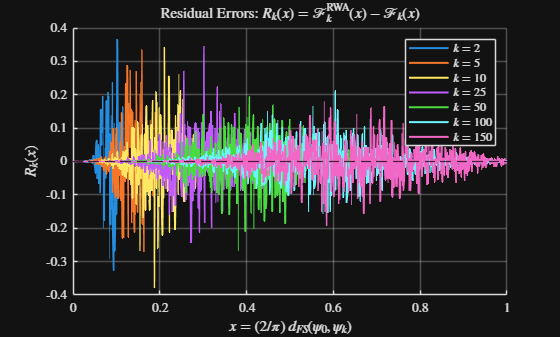


yline(0, 'k--', 'LineWidth', 1);
xlabel('$x = (2/\pi)\,d_{FS}(\psi_0,\psi_k)$');
ylabel('$R_k(x)$');
title('Residual Errors: $R_k(x)=\mathcal{F}_k^{\mathrm{RWA}}(x)-\mathcal{F}_k(x)$');
legend(arrayfun(@(k) sprintf('$k=%d$', k), Selected_Steps, 'UniformOutput', false), ...
    'Location', 'north east');
xlim([0, 1]);
grid on
hold off

%exportgraphics(gcf, 'Residuals_N=4.png', 'Resolution', 300);